# 행렬 연산

디지털 데이터가 있는 곳 어디에서든 행렬을 찾을 수 있습니다. 

        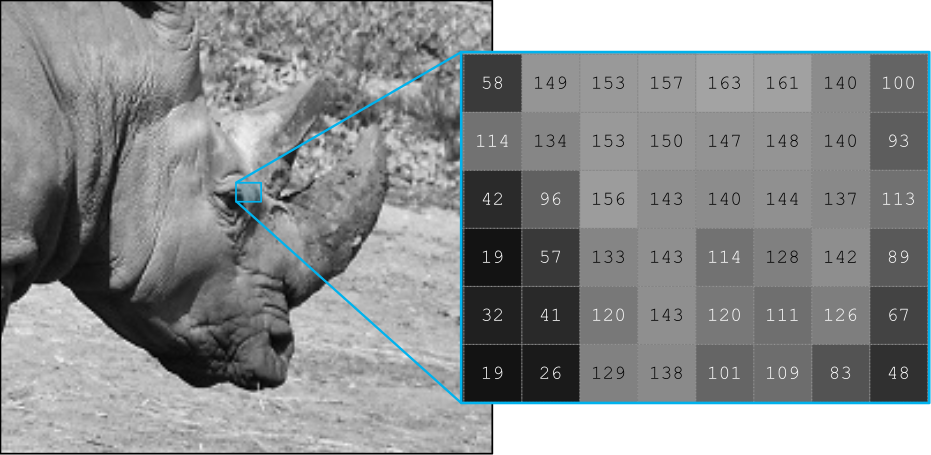

        * 회색조 이미지는 픽셀 강도로 구성된 큰 행렬입니다. *

 행렬의 하나 하나의 요소에 수학 연산을 적용하는 것은 쉽습니다.

    $58 \times 3 = 174$. 

 그러나 이러한 연산을 전체 행렬에 어떻게 적용하는지는 쉽게 알 수 없습니다. 

    
$$\left( \matrix{ 58 & 149 \cr 114 & 134 } \right) \times \left( \matrix{ 1 & 0 \cr -2 & 3 } \right) = ?$$


 이 라이브 스크립트에서는 기본 행렬 연산의 정의를 배우고 이를 MATLAB에서 직접 계산하는 방법을 연습합니다. 

 이 라이브 스크립트는 코드를 숨긴 상태로 사용하도록 만들어졌습니다. `VIEW` 탭을 선택하고 `Hide Code` 로 전환합니다. 

## 행렬 연산

-  이 라이브 스크립트에서는 $\mathbf{A}$ , $\mathbf{B}$ , $\mathbf{v}$ 및 $c$ 에 동일한 숫자 값이 사용됩니다. 

-  이 섹션을 실행하여 새로운 $\mathbf{A}$ , $\mathbf{B}$ , $\mathbf{v}$를 임의의 값으로 생성할 수 있습니다. 

 
[Ai,Bi,ci,vi] = DefineMatrices;
disp("행렬이 (재)정의 되었습니다.")

 여기에 정의된 행렬은 $10 \times 10$의 크기이지만 다음 섹션에서 크기를 조정하여 적절한 크기의 부분 행렬(submatrix)을 선택할 수 있습니다. 

### 정의

 행렬은 요소(elements)를 직사각형 형태로 모아둔 것입니다. 여기에 표시된 $m \times n$ 행렬에는 $m$ 행과 $n$ 열이 있습니다. 

    
$$\mathbf{A} = \left(\begin{array}{ccc}
a_{11}  &  a_{12} & \ldots  & a_{1n} \\
a_{21} & a_{22}   & \ldots  & a_{2n} \\
\vdots &  \vdots   & \ddots  & \vdots \\
a_{m1}  & a_{m2} & \ldots  & a_{mn} 
\end{array}\right)$$


 각 요소는 $a_{i,j}$ 로 표시됩니다. 여기서 $i$은 행을 나타내고 $j$는 열을 나타냅니다. 

  ** 실습.** 

- 다양한 크기의 $\mathbf{A}$를 얻기 위해 행($m$)과 열($n$) 수를 조정하세요. 

- 체크박스를 선택하면 숫자 행렬의 구체적인 예를 볼 수 있습니다. 

m = 5;
n = 5; 
numeric = false;
 
ValidateMatrices % 이 도우미 함수는 행렬이 정의되었는지 확인합니다.
if(numeric) 
    A = sym(Ai(1:m,1:n))
else
    A = sym('a',[m,n])
end

### 덧셈과 뺄셈

 두 개의 $n \times m$ 행렬을 더하려면 대응되는 요소끼리 더하세요. 

    
$$\mathbf{A} + \mathbf{B} = \left(\begin{array}{ccc}
a_{11}  &  a_{12} & \ldots  & a_{1n} \\
a_{21} & a_{22}   & \ldots  & a_{2n} \\
\vdots &  \vdots   & \ddots  & \vdots \\
a_{m1}  & a_{m2} & \ldots  & a_{mn} 
\end{array}\right) 
+ 
\left(\begin{array}{ccc}
b_{11}  &  b_{12} & \ldots  & b_{1n} \\
b_{21} & b_{22}   & \ldots  & b_{2n} \\
\vdots &  \vdots   & \ddots  & \vdots \\
b_{m1}  & b_{m2} & \ldots  & b_{mn} 
\end{array}\right)$$


               
$$= \left(\begin{array}{ccc}
a_{11} + b_{11}  &  a_{12} + b_{12} & \ldots  & a_{1n} +b_{1n}  \\
a_{21} + b_{21} & a_{22} + b_{22} & \ldots  & a_{2n} + b_{2n} \\
\vdots &  \vdots   & \ddots  & \vdots \\
a_{m1}  + b_{m1} & a_{m2} + b_{m2} & \ldots  & a_{mn}  + b_{mn} 
\end{array}\right)$$


 행렬을 빼려면 대응되는 요소끼리 뺍니다. 두 행렬을 더하거나 빼려면 크기가 같아야 합니다. 

 ** 연습 **. 행렬 $\mathbf{A}$ 및 $\mathbf{B}$ 을 뺍니다. 크기를 조정할 수 있습니다.  

m = 3;
n = 3; 
 
ValidateMatrices % 이 도우미 함수는 행렬이 정의되었는지 확인합니다.
A = sym(Ai(1:m,1:n));
B = sym(Bi(1:m,1:n));
displayFormula(["'A = '", "A", "'          B = '", "B"])
ShowSolution = false;
if(ShowSolution)
    AminusB = A-B;
    displayFormula(["'A - B = '", "AminusB"])
end

 ** 생각해봅시다. ** 아래에 표시된 행렬 $\mathbf{D}$을 살펴보세요. $\mathbf{A} + \mathbf{D}$ 를 계산할 수 있나요? 

BD = sym(Bi(1:m,1:(n+1)));
displayFormula(["'D = '", "BD"])

### 스칼라 곱하기

 행렬 $A$에 스칼라 $c$를 곱할 때 각 요소에 스칼라를 곱합니다. 

    
$$c\mathbf{A} = \left(\begin{array}{ccc}
ca_{11}  &  ca_{12} & \ldots  & ca_{1n} \\
ca_{21} & ca_{22}   & \ldots  & ca_{2n} \\
\vdots &  \vdots   & \ddots  & \vdots \\
ca_{m1}  & ca_{m2} & \ldots  & ca_{mn} 
\end{array}\right)$$


  ** 연습 **. 행렬 $\mathbf{A}$에 스칼라 $c$를 곱합니다. $\mathbf{A}$ 의 크기를 조정할 수 있습니다. 

m = 3;
n = 3; 
 
ValidateMatrices % 이 도우미 함수는 행렬이 정의되었는지 확인합니다.
A = sym(Ai(1:m,1:n));
displayFormula(["'A = '", "A"])
c = sym(ci);
displayFormula(["'c = '", "c"])
ShowSolution2 = false;
if(ShowSolution2)
    cA = ci*A;
    displayFormula(["'cA = '", "cA"])
end

### 열 벡터 곱셈

$m \times n$ 행렬 $\mathbf{A}$와 $n$ 개 요소를 가지는 열 벡터 $\mathbf{v}$를 곱하면 열 벡터가 됩니다. 곱셈의 결과물인 $\mathbf{Av}$의 원소는 $\mathbf{v}$ 벡터와 $\mathbf{A}$ 행의 내적입니다. 

    
$$\mathbf{Av} = \left(\begin{array}{ccc}
a_{11}  &  a_{12} & \ldots  & a_{1n} \\
a_{21} & a_{22}   & \ldots  & a_{2n} \\
\vdots &  \vdots   & \ddots  & \vdots \\
a_{m1}  & a_{m2} & \ldots  & a_{mn} 
\end{array}\right)
\left(\begin{array}{ccc}
v_{1} \\
v_{2} \\
\vdots \\
v_{n} 
\end{array}\right)$$


          
$$= \left(\begin{array}{ccc}
a_{11} v_1  +  a_{12} v_2  + \ldots  + a_{1n}v_n \\
a_{21} v_1  +  a_{22} v_2  + \ldots  + a_{2n}v_n\\
\vdots \\
a_{m1} v_1  +  a_{m2} v_2  + \ldots  + a_{mn}v_n\\
\end{array}\right)$$


 $\mathbf{A}$ 행렬의 행과 벡터 $\mathbf{v}$의 내적을 취하려면 $\mathbf{A}$의 열 수가 $\mathbf{v}$ 의 원소 수와 일치해야합니다. 다시 말해, $\mathbf{v}$에 $n$개 원소가 있어야 한다는 것을 의미합니다. 

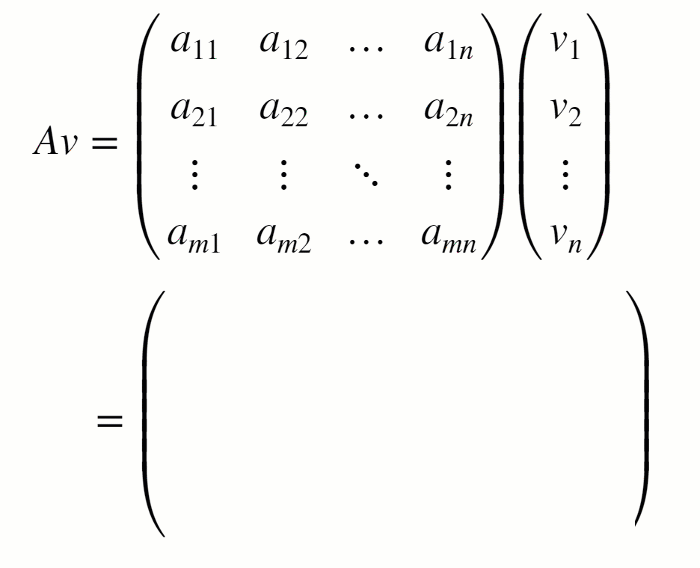

* 행렬-벡터 곱셈의 애니메이션. 결과의 각 항목은 행렬 행과 벡터의 내적을 취하여 생성됩니다. *

 ** 연습 **. 행렬-벡터 곱 $\mathbf{A} \mathbf{v}$ 을 계산합니다. 크기를 조정할 수 있습니다. 

m = 3;
n = 3; 
 
ValidateMatrices % 이 도우미 함수는 행렬이 정의되었는지 확인합니다.
A = sym(Ai(1:m,1:n));
displayFormula(["'A = '", "A"])
v = sym(vi(1:n));
displayFormula(["'v = '", "v"])
ValidateMatrices % 이 도우미 함수는 행렬이 정의되었는지 확인합니다.
ShowSolution3 = false;
if(ShowSolution3)
    Av = A*v;
    displayFormula(["'Av = '", "Av"])
end

 ** 생각해봅시다. ** 아래에 표시된 벡터 $\mathbf{u}$를 고려하세요. $\mathbf{A}\mathbf{u}$ 를 계산할 수 있나요? 

u = sym(vi(1:(n+2)));
displayFormula(["'u = '", "u"])

### 다른 행렬과의 곱셈

$m \times n$ 행렬 $\mathbf{A}$과 $n \times p$ 행렬 $\mathbf{B}
$의 곱은 아래에 정의된 $m \times p$ 행렬 $\mathbf{C}
$입니다. 행렬간의 곱을 정의하려면 $\mathbf{A}$ 및 $\mathbf{B}
$의 "내부" 차원이 일치해야 합니다. 

    
$$\mathbf{AB} = \left(\begin{array}{ccc}
a_{11}  &  a_{12} & \ldots  & a_{1n} \\
a_{21} & a_{22}   & \ldots  & a_{2n} \\
\vdots &  \vdots   & \ddots  & \vdots \\
a_{m1}  & a_{m2} & \ldots  & a_{mn} 
\end{array}\right)

\left(\begin{array}{ccc}
b_{11}  & b_{12} & \ldots  & b_{1p} \\
b_{21} & b_{22}   & \ldots  & b_{2p} \\
\vdots &  \vdots   & \ddots  & \vdots \\
b_{n1}  & b_{n2} & \ldots  & b_{np} 
\end{array}\right)$$


          
$$=
\left(\begin{array}{ccc}
c_{11}  & c_{12} & \ldots  & c_{1p} \\
c_{21} & c_{22}   & \ldots  & c_{2p} \\
\vdots &  \vdots   & \ddots  & \vdots \\
c_{m1}  & c_{m2} & \ldots  & c_{mp} 
\end{array}\right)$$


 여기서 $c_{ij}
$는 아래와 같습니다.

    
$$c_{ij} = \sum_{k} a_{ik}b_{kj}$$


곱하고자 하는 두 행렬의 내부 크기가 일치하지 않으면 $A$ 행은 $B$ 열과 길이가 같지 않으며 이 합계는 정의되지 않습니다. 

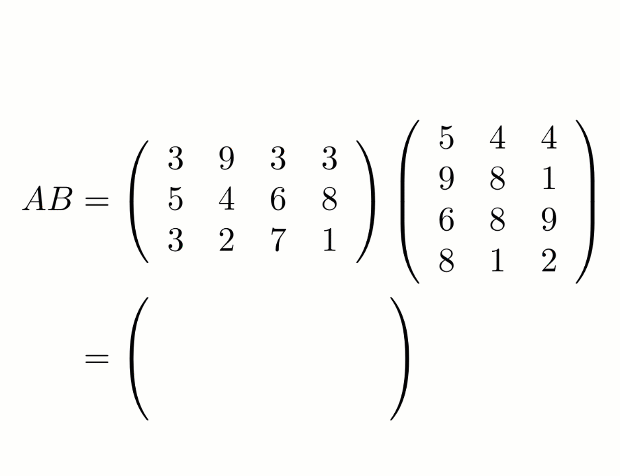

* 행렬 곱셈의 예. 곱의 각 요소는 A 행과 B 열의 내적을 취하여 생성됩니다. *

 ** 연습 **. 행렬 $A$ 과 $B$ 를 곱합니다. 크기를 조정할 수 있습니다. 

m = 3;
n = 3; 
p = 3;
 
ValidateMatrices % 이 도우미 함수는 행렬이 정의되었는지 확인합니다.
A = sym(Ai(1:m,1:n));
displayFormula(["'A = '", "A"])
B = sym(Bi(1:n,1:p));
displayFormula(["'B = '", "B"])
ShowSolution3 = false;
if(ShowSolution3)
    AB = A*B;
    displayFormula(["'AB = '", "AB"])
end

 ** 생각해봅시다. **

 1. 아래의 행렬 $\mathbf{C}$에 대하여,

C = sym(Ai(end-n+1:end,end-n+1:end));
displayFormula(["'C = '", "C"])

 다음 중 정의할 수 있는 행렬곱은 무엇입니까? 

 (a) $\mathbf{AC}$

 (b) $\mathbf{CA}$

 (c) $\mathbf{BC}$

 (d) $\mathbf{CB}$

 2. 행렬 곱셈은 교환 가능합니까(즉, $\mathbf{AB}= \mathbf{BA}$ 입니까)? 

## 특수 행렬

 슬라이더를 사용하여 행렬의 크기를 지정하거나 **특수 행렬 보기**를 클릭합니다. 

n = 4; 
 

** 정방 행렬 (square matrix)**

정방 행렬의 행과 열 개수는 같습니다. 예를 들어, $n \times n$ 행렬 $\mathbf{A}$는: 

A = sym(Ai(1:n,1:n));
displayFormula(["'A = '", "A"])

** 대각 행렬 (diagonal matrix)**

 *대각 * 행렬은 주대각선 이외의 모든 원소의 값이 0인 정방 행렬입니다. 

DA = sym(diag(Ai(1:n,n)));
displayFormula(["'D = '", "DA"])

** 단위 행렬 (identity matrix)**

*단위  *행렬(일반적으로 $\mathbf{I}$ 로 표시됨)은 모든 대각선 요소가 1인 대각 행렬입니다. 

I1 = sym(diag(ones(n,1))); 
displayFormula(["'I = '", "I1"])

어떤 행렬이라도 행렬 $\mathbf{I}$를 곱하면 원래의 행렬 그대로 유지되기 때문에 단위 행렬이라는 이름이 붙었습니다. 

    $\mathbf{A}\mathbf{I} = \mathbf{A}$. 

 ** 연습 **. $m \times n$ 행렬 $\mathbf{A}$ 에 $n \times n$ 항등식 $\mathbf{I}$ 을 곱합니다. 

m = 3;
n = 4; 
 
ValidateMatrices % 이 도우미는 행렬이 정의되었는지 확인합니다.
I1 = sym(diag(ones(n,1))); 
A = sym(Ai(1:m,1:n));
displayFormula(["'A = '", "A","'    I = '", "I1"])
ShowSolution3 = false;
if(ShowSolution3)
    AI = A*I1;
    displayFormula(["'AI = '", "AI"])
end

 ** 생각해봅시다. **

-  행렬에 $\mathbf{I}$를 더한 후에도 그 행렬은 동일하게 유지됩니까? 즉, $\mathbf{A} + \mathbf{I} \stackrel{?}{=} \mathbf{A}$ 입니까? 

-  $\mathbf{I} \mathbf{A}$와 같이 곱한 결과는 무엇입니까? 

## MATLAB의 행렬 연산

MATLAB에서는 숫자 행렬(numeric matrix)을 더 자주 정의하게 됩니다. 그러나 보다 일반적인 계산의 경우 Symbolic Math Toolbox를 사용하여 기호 행렬(symbolic matrix)을 정의할 수 있습니다. 숫자 행렬의 기본 함수는 기호 행렬에서도 작동합니다. 

### 숫자 행렬

** 1. 숫자 행렬을 정의합니다. ** MATLAB에서는 각 원소를 나열하여 숫자 행렬을 정의합니다. 이때 공백( ) 또는 쉼표(,)를 사용하여 원소를 구분하고 세미콜론( `;` )을 사용하여 행을 구분합니다.  예를 들어, 아래와 같은 행렬에 대해, 

    
$$\mathbf{A} = \left( \matrix{ 3 &  5 \cr 10 & 12} \right)$$


MATLAB에서는 아래와 같은 코드를 쓸 수 있습니다.

  ** 실습. **아래의 행렬 

    
$$\mathbf{C} = \left( \matrix{ 1 &  2 \cr 3 & 4} \right)$$


을 숫자 행렬로 정의합니다.

C = [];
 
IsEqualCheck(C,[1 2; 3 4]);

  ** Task **. 또한 행렬 $\mathbf{R}$ 을 정의합니다. 

    
$$\mathbf{R} =\mathrm{}\left(\begin{array}{cc}
4 & 2\\
2 & 9\\
1 & 3
\end{array}\right)$$


R = [];
 
IsEqualCheck(R,[4 2; 2 9; 1 3]);

** 2. 행렬 연산을 수행합니다. ** 표준 산술 연산자(+, -, * )를 사용하여 MATLAB에서 기본 작업을 수행할 수 있습니다. 추가 행렬 $\mathbf{P}$가 아래에 정의되어 있습니다. 

P = [1 -2; 1 -1; 2 5]

  ** 실습.** MATLAB 명령을 사용하여 합 `R + P`를 계산합니다. 

RpP = [ ] 
try
   IsEqualCheck(RpP,R+P);
catch ME
   warning("Check failed because: " + ME.message) 
end

  ** 실습.** 합 $C + R$ `을 계산합니다.`

C = [1 2; 3 4];
R = [4 2; 2 9; 1 3];
try
    
catch ME
   disp("Error: " + ME.message) 
end

 왜 작업이 실패하나요? 

  ** Task **. 곱 $\mathbf{RC}$를 계산합니다. 힌트: 곱셈 연산자( * )를 사용하세요. 

RC = [ ]
IsEqualCheck(RC,R*C);

 ** 생각해봅시다. ** $\mathbf{CR}$을 계산하지 않은 이유는 무엇입니까? 

  ** Task **. `R과` `P`의 요소별 곱`(R⊙P)`을 계산합니다. 

  ** 전문가 팁 ** : MATLAB은 요소별 행렬 곱셈도 허용합니다. 요소별 곱셈은 를 사용하여 정의됩니다. * 연산자. 

RP = [ ]
try
    IsEqualCheck(RP,R.*P);
catch ME
   warning("Check failed because: " + ME.message) 
end

 ** 생각해봅시다. ** 요소별 곱의 행렬 크기 조건은 무엇입니까? 

** 3. 특수 행렬. **

  ** Task **. `eye(n)` 구문과 함께 [`eye`](https://www.mathworks.com/help/matlab/ref/eye.html) 함수를 사용하여 $4 \times 4$ 단위 행렬을 정의합니다. 

I = [ ]
IsEqualCheck(eye(4),I);

  ** Task **. MATLAB에서 대각 행렬 $D$를 정의합니다.

    
$$\mathrm{D\ =\ }\mathrm{}\left(\begin{array}{cccc}
7 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 3 & 0\\
0 & 0 & 0 & 1
\end{array}\right)$$


 `diag(v)` 구문과 함께 [`diag`](https://www.mathworks.com/help/matlab/ref/diag.html) 함수를 사용하여 $n \times n$ 대각 행렬을 만들 수 있습니다. 여기서 $v$`는` $n$-원소 벡터입니다. 

 먼저 대각선에 배치될 요소를 포함하는 벡터를 정의합니다. 

v = [ ]
IsEqualCheck(reshape(v,1,[]),[7 1 3 1]);

 그런 다음 `diag` 함수 사용하여 행렬을 생성합니다. 

D = [ ]
IsEqualCheck(D,diag(v));

  ** Task **. 곱 $\mathbf{ID}$를 계산합니다. 

ID = [ ]
IsEqualCheck(ID,I*D);

### 기호 행렬

 MATLAB에서는 기호 행렬을 정의하는 두 가지 기본 방법이 있습니다. 

 1. 일반 $m \times n$ 기호 행렬 $\mathbf{A}$를 정의하려면 다음 구문과 함께 [`syms`](https://www.mathworks.com/help/symbolic/syms.html) 함수를 사용할 수 있습니다. 

 2. 지정된 항목으로 기호 행렬을 정의하려면 먼저 기호 변수를 정의한 다음 행렬에 넣을 수 있습니다. 예를 들면 아래와 같습니다.

  ** Task **. syms 명령을 사용하여 아래 표시된 두 행렬을 정의합니다. 


$$\mathbf{H} = 
\left(\begin{array}{cc}
H_{1,1}  & H_{1,2} \\
H_{2,1}  & H_{2,2} \\
H_{3,1}  & H_{3,2} 
\end{array}\right)$$
        
$$\mathbf{G} = 
\left(\begin{array}{cc}
a & 1\\
b & -3
\end{array}\right)$$


 일반 구문을 사용하여 `H`을 정의합니다. 

H = [];
G = [];
 
H
IsEqualCheck([3 2],size(H));

 `a` 및 `b`를 기호 변수로 정의합니다. 

 `G`를 정의합니다. 기호 변수 `a` 및 `b` 를 사용합니다. 

 
syms a b
IsEqualCheck(G,[a 1; b -3]);

  ** Task **. 곱 $\mathbf{HG}$ 을 계산합니다. 

HG = [ ]
IsEqualCheck(HG,H*G);

### 응용 프로그램: 회색조 이미지

 회색조 이미지는 일반적으로 [0,255] 범위의 값을 갖는 8비트 정수의 행렬입니다. MATLAB에서 두 개의 이미지를 로드하고 표시하려면 이 섹션을 실행하십시오. 

 이 섹션을 실행하려면 이미지 `rhino_gs.png` 및 `giraffe_gs.png`가 MATLAB 경로에 있어야 합니다. 

G = double(imread("giraffe_gs.png"));
R = double(imread("rhino_gs.png"));
imshowpair(G,R,"montage")
 

 각 이미지는 숫자 행렬로 저장됩니다. 이미지가 상당히 크기 때문에 모든 숫자 값을 표시하는 것은 비현실적입니다. 대신 [배열 인덱싱](https://www.mathworks.com/help/matlab/math/array-indexing.html) 을 사용하여 범위를 선택하여 픽셀 값의 작은 하위 행렬을 표시할 수 있습니다. 예를 들어, 이미지 `G` 의 20-30행과 40-60열의 하위 행렬을 선택하려면 

를 사용합니다. 

  ** 실습. ** 코뿔소 이미지는 `R` 에 저장됩니다. 행 100~106과 열 300~320에서 `R`의 하위 행렬을 선택합니다. 

Rsub = [ ];
Rsub
IsEqualCheck(Rsub,R(100:106,300:320));

 이 두 이미지는 정사각형이고 크기가 동일하므로 표준 행렬 연산을 적용할 수 있습니다. 

  ** 실습.** 두 개의 이미지 행렬 `G` 및 `R`를 더해봅니니다. G+R은 어떤 이미지를 보여줄까요? 

GpR = [ ];
IsEqualCheck(GpR,G+R);
imshow(GpR,[])
title("G+R")

  ** 실습.** `255-R,` `255-R를 계산하면 `어떤 이미지를 보여줄까요? 이 8비트 이미지의 픽셀 값은 [0,255] 범위에 있음을 기억하세요. 

result = [ ];
IsEqualCheck(result,255-R);
imshow(result,[])
title("255-R")

  ** 실습.** 이미지 행렬 `G` 와 `R` 를 곱합니다. GR은 어떤 모습을 보여줄까요? 

GR= [ ];
IsEqualCheck(GR,G*R);
imshow(GR,[])
title("GR")

  ** 실습.** 따라서 행렬 곱셈은 회색조 이미지에 대해 정확히 의미 있는 결과를 생성하지 않습니다. 더 의미 있는 곱셈은 [요소별 곱셈](https://www.mathworks.com/help/matlab/ref/times.html) (⊙으로 표시됨)일 수 있습니다. `G` 와 `R` 의 요소별 곱을 계산합니다. `G⊙R`는 어떤 이미지를 보여줄까요? 

GdR= [ ];
IsEqualCheck(GdR,G.*R);
imshow(GdR,[])
title("G⊙R")

 ** 생각해봅시다. ** 표준 행렬 곱셈은 요소별 곱셈보다 계산하고 이해하기가 더 어렵습니다. 요소별 제품이 표준으로 간주되지 않는 이유는 무엇입니까? 

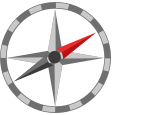** 추가 탐구 **

- 온라인 교육 과정[ Introduction to Linear Algebra with MATLAB](https://matlabacademy.mathworks.com/details/introduction-to-linear-algebra-with-matlab/linalg)에서 행렬 연산 및 기타 선형 대수 주제에 대해 자세히 알아볼 수 있습니다. 

- Symbolic Math에 대해 자세히 알아보려면 온라인 교육 과정 [Introduction to Symbolic Math with MATLAB](https://matlabacademy.mathworks.com/details/introduction-to-symbolic-math-with-matlab/symbolic)을 확인하세요. 

function [Ai,Bi,ci,vi] = DefineMatrices
% 이 함수는 행렬을 정의합니다
    Ai = randi(9,10,10);
    Bi = randi(9,10,10);
    ci = randi(8)+1;
    vi = randi(9,10,1);
end

function ValidateMatrices
% 이 함수는 행렬이 정의되었는지 확인합니다.
    try
        Ai = evalin("base","Ai");
    catch ME
        warning("Matrices were not defined. They will be auto-populated.")
        evalin("base","[Ai,Bi,ci,vi] = DefineMatrices();");
    end
end

function correct = IsEqualCheck(UserSubmission,CorrectAnswer)
% 이 기능은 두 결과가 동일한지 확인하고 피드백을 표시합니다.
    correct = true;
    if( isequal(UserSubmission,CorrectAnswer) )
        disp("Correct!")
    else
        warning("Your answer does not match the expected result.")
        correct = false;
    end
end

% Suppress unused suggestions
%#ok<*UNRCH> 
%#ok<*NASGU> 
%#ok<*NBRAK> 